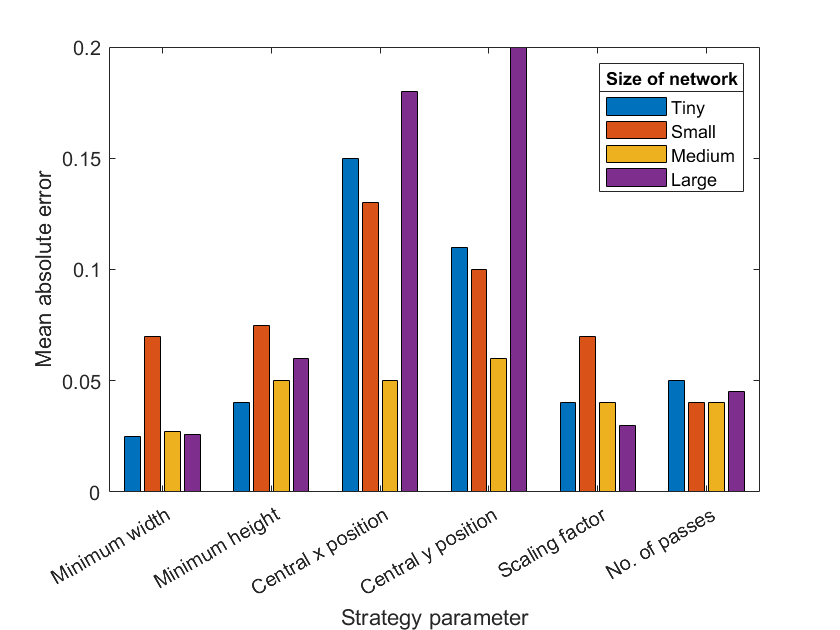

% c2o
c2o_mat = [0.025 0.07 0.027 0.026 ; 0.04 0.075 0.05 0.06 ; 0.15 0.13 0.05 0.18; 0.11 0.1 0.06 0.2; 0.04 0.07 0.04 0.03 ; 0.05 0.04 0.04 0.045];

figure()
bar(c2o_mat)
xticklabels(gca,{'Minimum width','Minimum height','Central x position','Central y position','Scaling factor','No. of passes'})
xlabel('Strategy parameter')
ylabel('Mean absolute error')
lgd = legend({'Tiny','Small','Medium','Large'});
title(lgd,'Size of network')

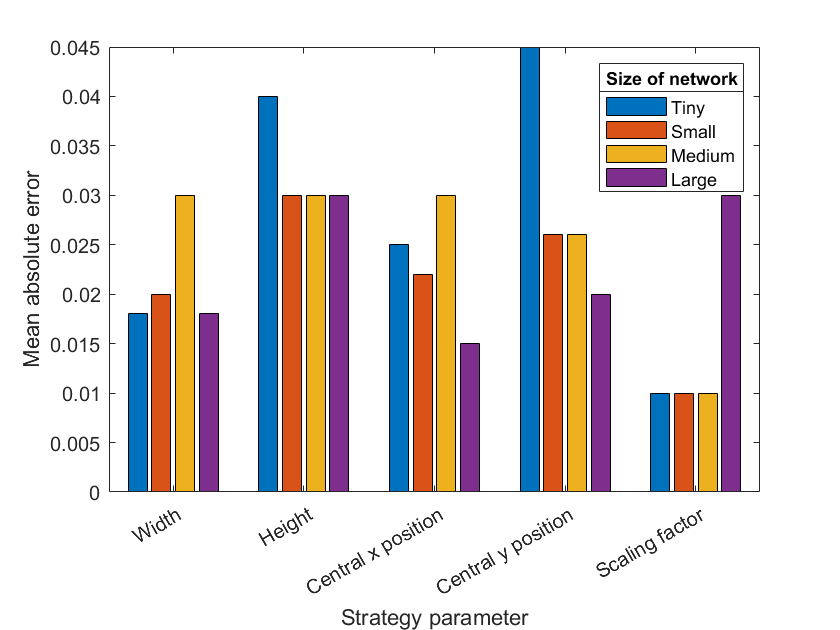

% over
over_mat = [0.018 0.02 0.03 0.018 ; 0.04 0.03 0.03 0.03 ; 0.025 0.022 0.03 0.015 ; 0.045 0.026 0.026 0.02 ; 0.01 0.01 0.01 0.03];

figure()
bar(over_mat)
xticklabels(gca,{'Width','Height','Central x position','Central y position','Scaling factor','No. of passes'})
xlabel('Strategy parameter')
ylabel('Mean absolute error')
lgd = legend({'Tiny','Small','Medium','Large'});
title(lgd,'Size of network')

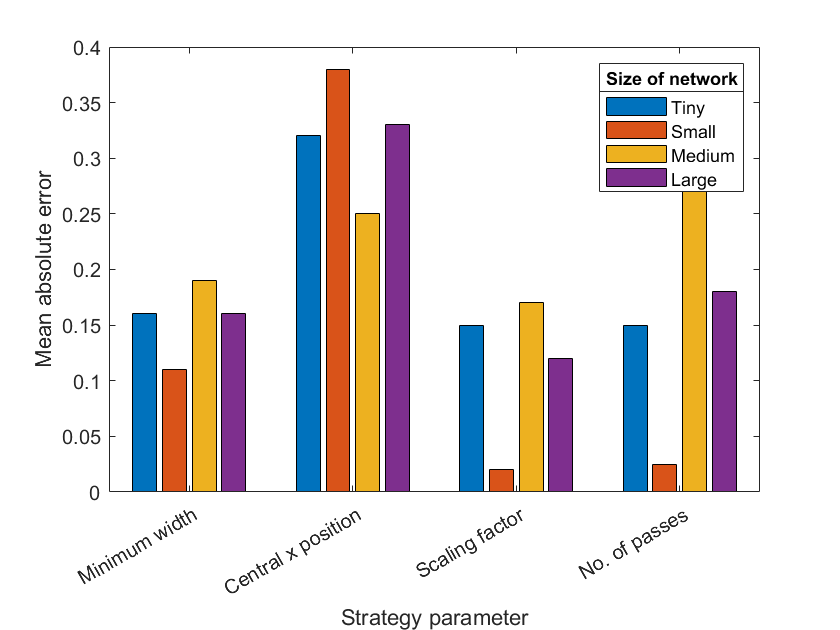

% ver
ver_mat = [0.16 0.11 0.19 0.16; 0.32 0.38 0.25 0.33; 0.15 0.02 0.17 0.12; 0.15 0.025 0.3 0.18];

figure()
bar(ver_mat)
xticklabels(gca,{'Minimum width','Central x position','Scaling factor','No. of passes'})
xlabel('Strategy parameter')
ylabel('Mean absolute error')
lgd = legend({'Tiny','Small','Medium','Large'});
title(lgd,'Size of network')

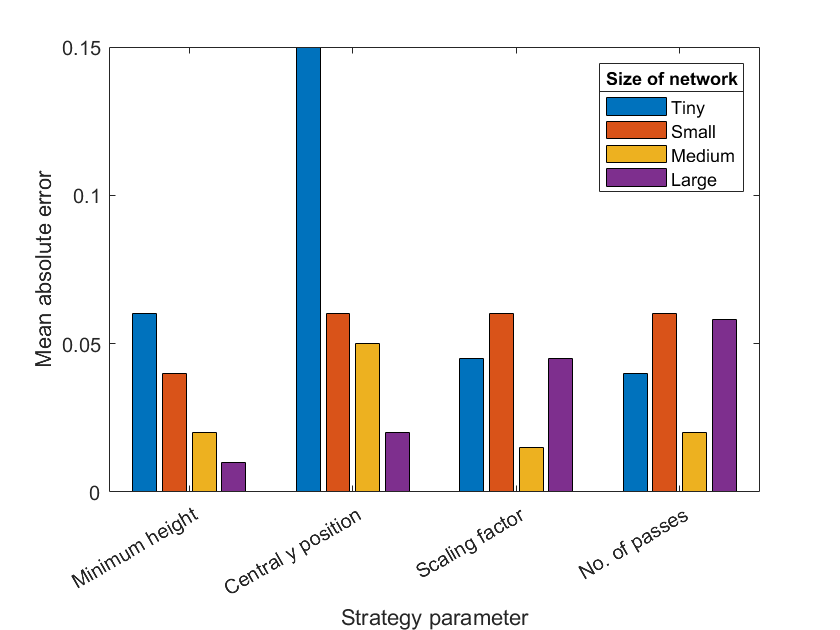

% hor
hor_mat = [0.06 0.04 0.02 0.01 ; 0.15 0.06 0.05 0.02 ; 0.045 0.06 0.015 0.045 ; 0.04 0.06 0.02 0.058];

figure()
bar(hor_mat)
xticklabels(gca,{'Minimum height','Central y position','Scaling factor','No. of passes'})
xlabel('Strategy parameter')
ylabel('Mean absolute error')
lgd = legend({'Tiny','Small','Medium','Large'});
title(lgd,'Size of network')

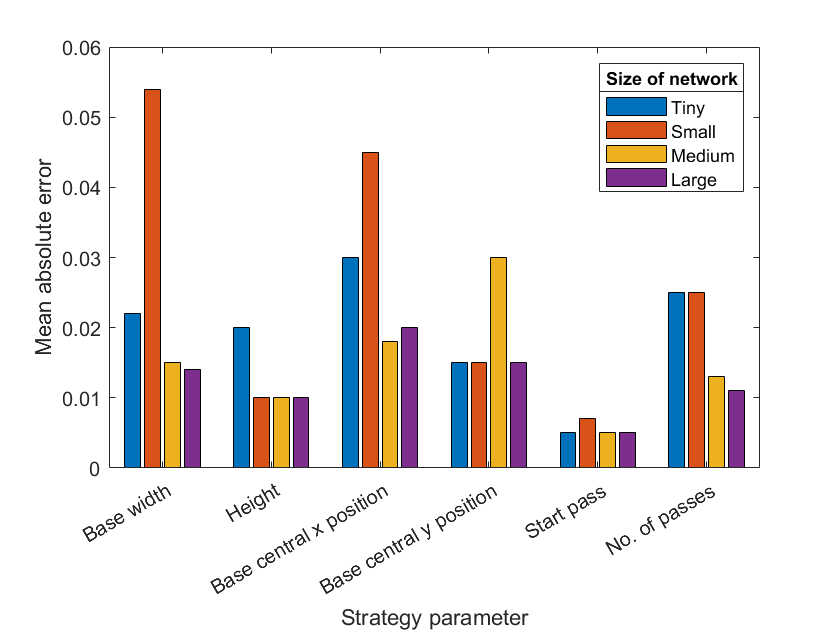

% tri
tri_mat = [0.022 0.054 0.015 0.014 ; 0.02 0.01 0.01 0.01 ; 0.03 0.045 0.018 0.02 ; 0.015 0.015 0.03 0.015 ; 0.005 0.007 0.005 0.005 ; 0.025 0.025 0.013 0.011];

figure()
bar(tri_mat)
xticklabels(gca,{'Base width','Height','Base central x position','Base central y position','Start pass','No. of passes'})
xlabel('Strategy parameter')
ylabel('Mean absolute error')
lgd = legend({'Tiny','Small','Medium','Large'});
title(lgd,'Size of network')

layer1 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_0_c2o.csv');
layer2 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_1_c2o.csv');
layer3 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_2_c2o.csv');
layer4 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_3_c2o.csv');

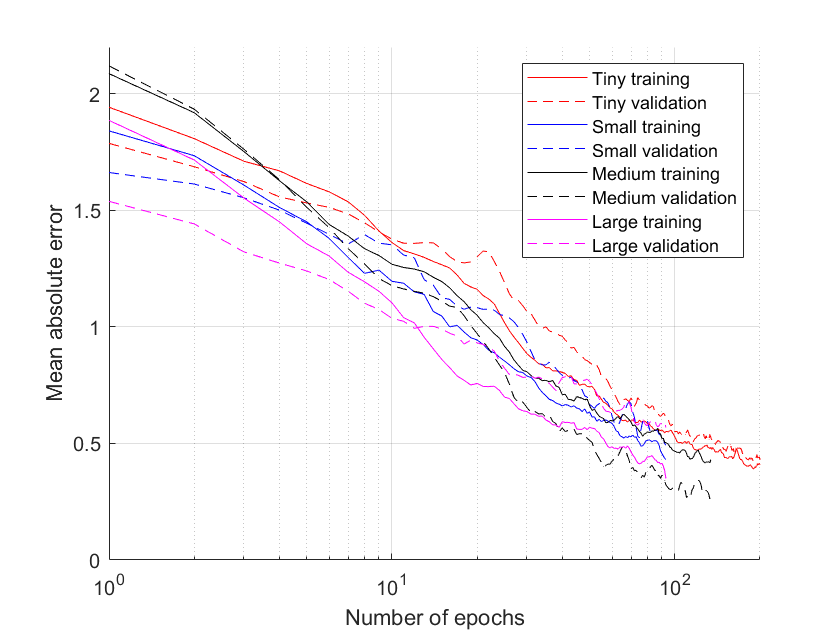

% c2o
fig = figure();
hold on

train1 = smooth(sum(layer1(:,9:14),2));
train2 = smooth(sum(layer2(:,9:14),2));
train3 = smooth(sum(layer3(:,9:14),2));
train4 = smooth(sum(layer4(:,9:14),2));
val1 = smooth(sum(layer1(:,22:end),2));
val2 = smooth(sum(layer2(:,22:end),2));
val3 = smooth(sum(layer3(:,22:end),2));
val4 = smooth(sum(layer4(:,22:end),2));

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
ylim([0 2.2])
xlim([1 200])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
legend({'Tiny training','Tiny validation','Small training','Small validation','Medium training','Medium validation','Large training','Large validation'})

saveas(fig, '..\Python\data\plots\layer2_c2o_cum.jpg')


fig = figure()

fig =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


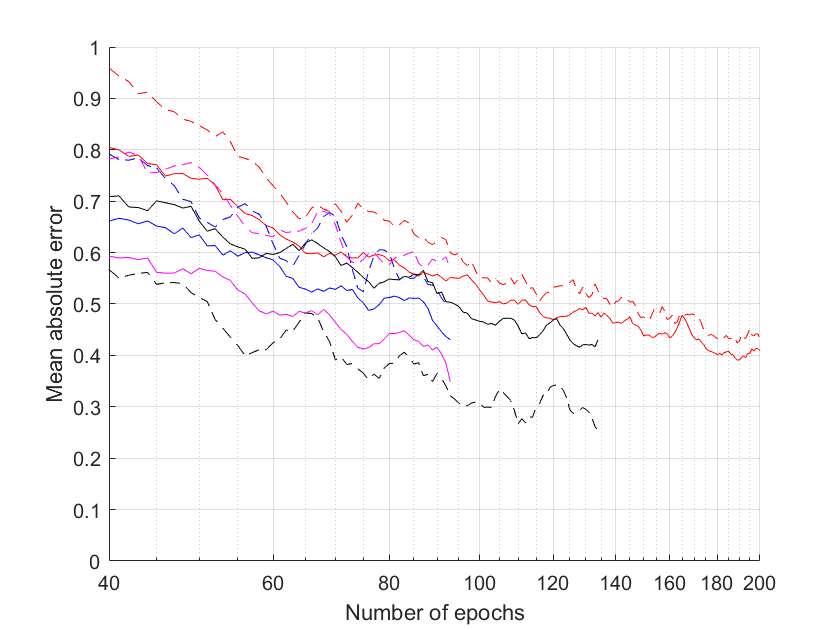

hold on

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([40 200])
ylim([0 1])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
saveas(fig, '..\Python\data\plots\layer2_c2o_cum_zoomed.jpg')

layer1 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_0_over.csv');
layer2 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_1_over.csv');
layer3 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_2_over.csv');
layer4 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_3_over.csv');

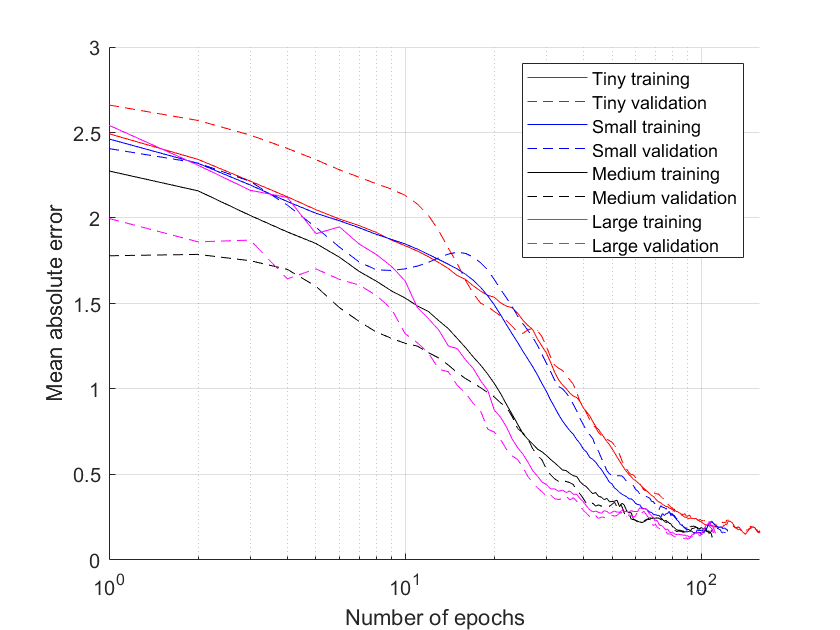

% over
fig = figure();
hold on

train1 = smooth(sum(layer1(:,8:12),2));
train2 = smooth(sum(layer2(:,8:12),2));
train3 = smooth(sum(layer3(:,8:12),2));
train4 = smooth(sum(layer4(:,8:12),2));
val1 = smooth(sum(layer1(:,19:end),2));
val2 = smooth(sum(layer2(:,19:end),2));
val3 = smooth(sum(layer3(:,19:end),2));
val4 = smooth(sum(layer4(:,19:end),2));

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
legend({'Tiny training','Tiny validation','Small training','Small validation','Medium training','Medium validation','Large training','Large validation'})

saveas(fig, '..\Python\data\plots\layer2_over_cum.jpg')

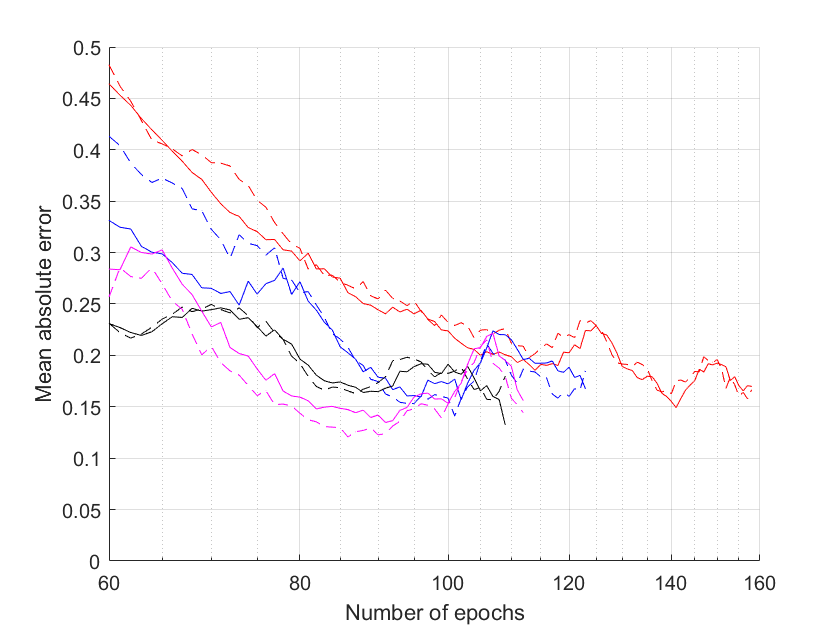


fig = figure();
hold on

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([60 160])
ylim([0 0.5])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
saveas(fig, '..\Python\data\plots\layer2_over_cum_zoomed.jpg')

layer1 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_0_ver.csv');
layer2 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_1_ver.csv');
layer3 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_2_ver.csv');
layer4 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_3_ver.csv');

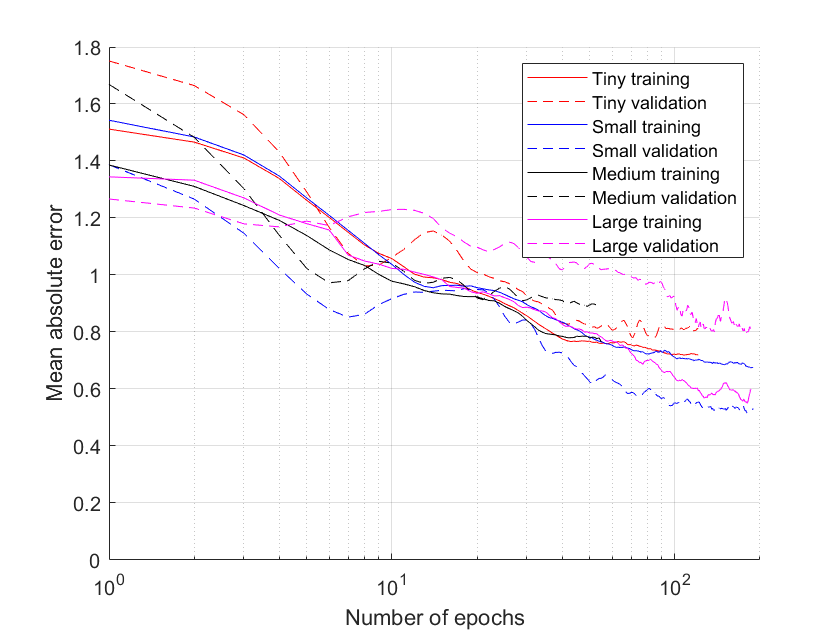

% ver
fig = figure();
hold on

train1 = smooth(sum(layer1(:,7:10),2));
train2 = smooth(sum(layer2(:,7:10),2));
train3 = smooth(sum(layer3(:,7:10),2));
train4 = smooth(sum(layer4(:,7:10),2));
val1 = smooth(sum(layer1(:,16:end),2));
val2 = smooth(sum(layer2(:,16:end),2));
val3 = smooth(sum(layer3(:,16:end),2));
val4 = smooth(sum(layer4(:,16:end),2));

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([1 200])
ylim([0 1.8])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
legend({'Tiny training','Tiny validation','Small training','Small validation','Medium training','Medium validation','Large training','Large validation'})

saveas(fig, '..\Python\data\plots\layer2_ver_cum.jpg')

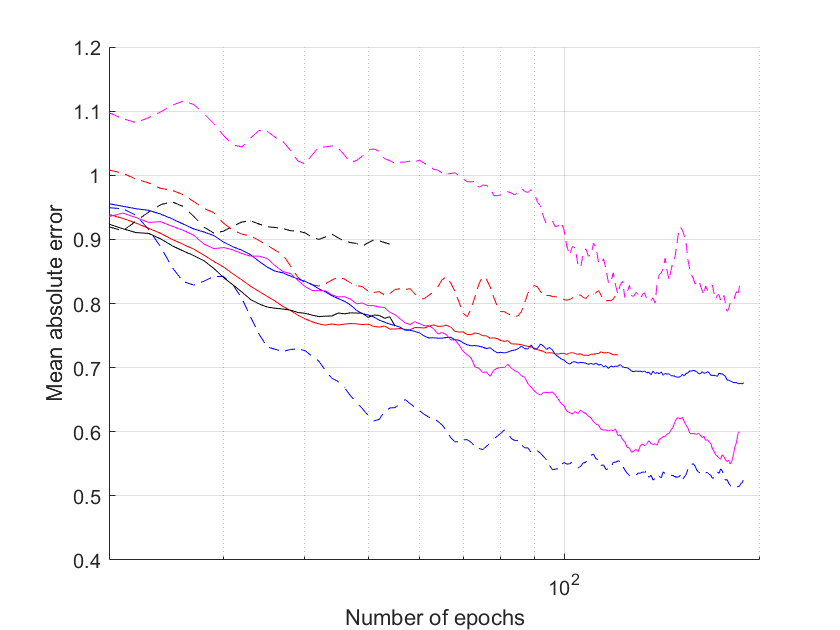


fig = figure();
hold on

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([20 200])
ylim([0.4 1.2])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
saveas(fig, '..\Python\data\plots\layer2_ver_cum_zoomed.jpg')

layer1 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_0_hor.csv');
layer2 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_1_hor.csv');
layer3 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_2_hor.csv');
layer4 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_3_hor.csv');

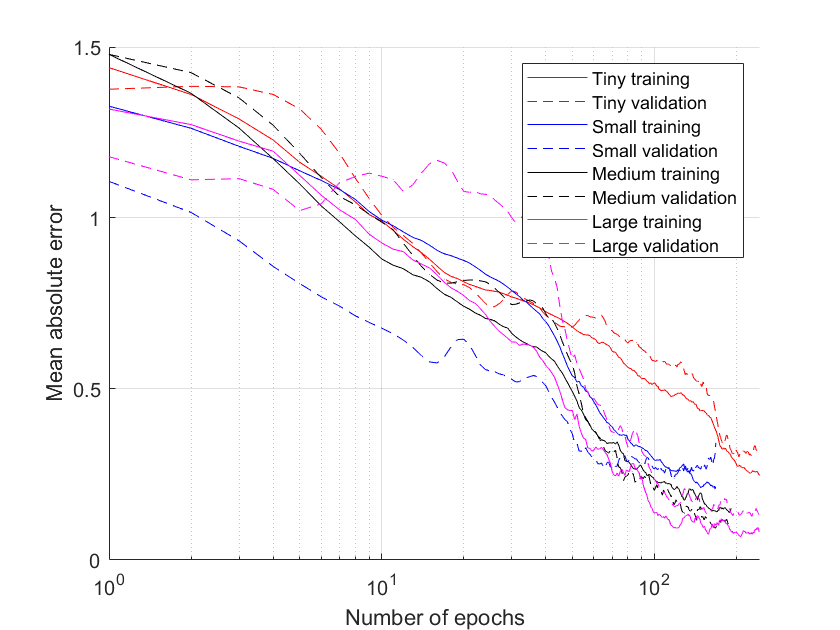

% hor
fig = figure();
hold on

train1 = smooth(sum(layer1(:,7:10),2));
train2 = smooth(sum(layer2(:,7:10),2));
train3 = smooth(sum(layer3(:,7:10),2));
train4 = smooth(sum(layer4(:,7:10),2));
val1 = smooth(sum(layer1(:,16:end),2));
val2 = smooth(sum(layer2(:,16:end),2));
val3 = smooth(sum(layer3(:,16:end),2));
val4 = smooth(sum(layer4(:,16:end),2));

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
legend({'Tiny training','Tiny validation','Small training','Small validation','Medium training','Medium validation','Large training','Large validation'})

saveas(fig, '..\Python\data\plots\layer2_hor_cum.jpg')

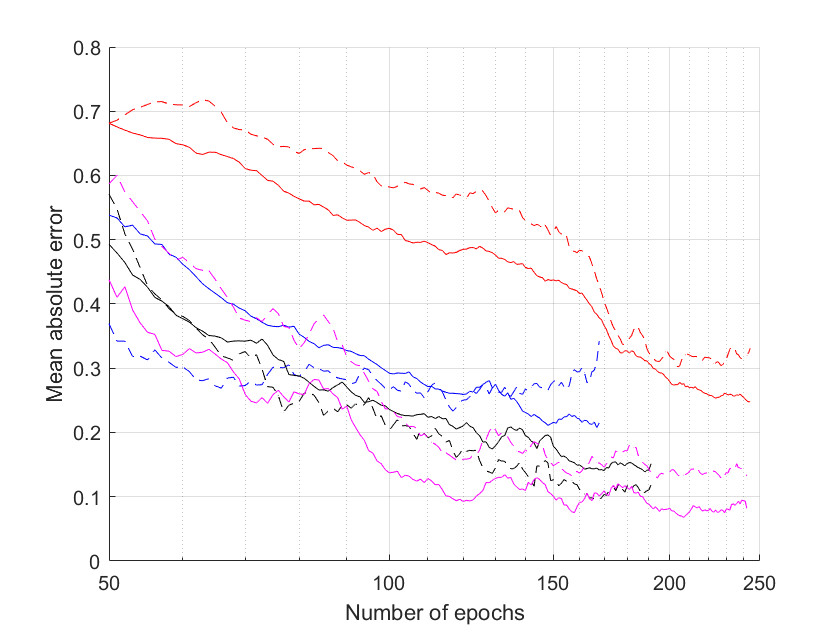


fig = figure();
hold on

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([50 250])
ylim([0 0.8])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
saveas(fig, '..\Python\data\plots\layer2_hor_cum_zoomed.jpg')

layer1 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_0_tri.csv');
layer2 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_1_tri.csv');
layer3 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_2_tri.csv');
layer4 = readmatrix('C:\Users\adsk1\Documents\FYP\Python\data\plots\overfit_history_layer2_3_tri.csv');

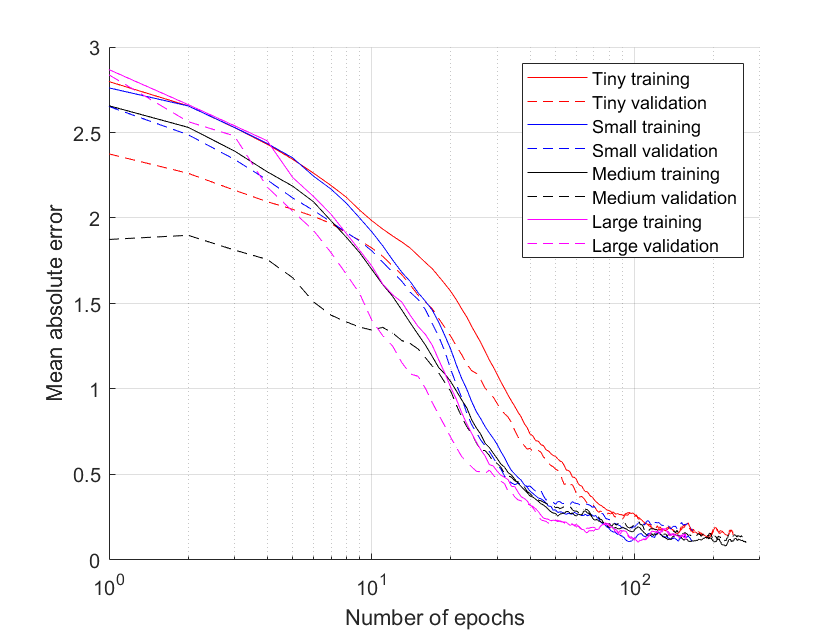

% tri
fig = figure();
hold on

train1 = smooth(sum(layer1(:,9:14),2));
train2 = smooth(sum(layer2(:,9:14),2));
train3 = smooth(sum(layer3(:,9:14),2));
train4 = smooth(sum(layer4(:,9:14),2));
val1 = smooth(sum(layer1(:,22:end),2));
val2 = smooth(sum(layer2(:,22:end),2));
val3 = smooth(sum(layer3(:,22:end),2));
val4 = smooth(sum(layer4(:,22:end),2));

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([0 300])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
legend({'Tiny training','Tiny validation','Small training','Small validation','Medium training','Medium validation','Large training','Large validation'})

saveas(fig, '..\Python\data\plots\layer2_tri_cum.jpg')

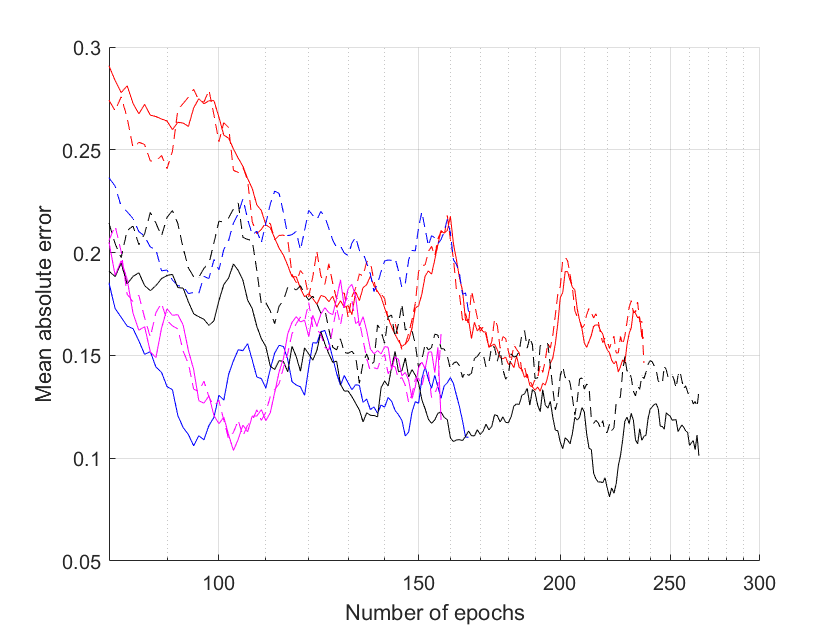


fig = figure();
hold on

plot(layer1(:,1),train1,'r-')
plot(layer1(:,1),val1,'r--')
plot(layer2(:,1),train2,'b-')
plot(layer2(:,1),val2,'b--')
plot(layer3(:,1),train3,'k-')
plot(layer3(:,1),val3,'k--')
plot(layer4(:,1),train4,'m-')
plot(layer4(:,1),val4,'m--')
set(gca,'xscale','log')
xlim([80 300])
ylim([0.05 0.3])

xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on
saveas(fig, '..\Python\data\plots\layer2_tri_cum_zoomed.jpg')

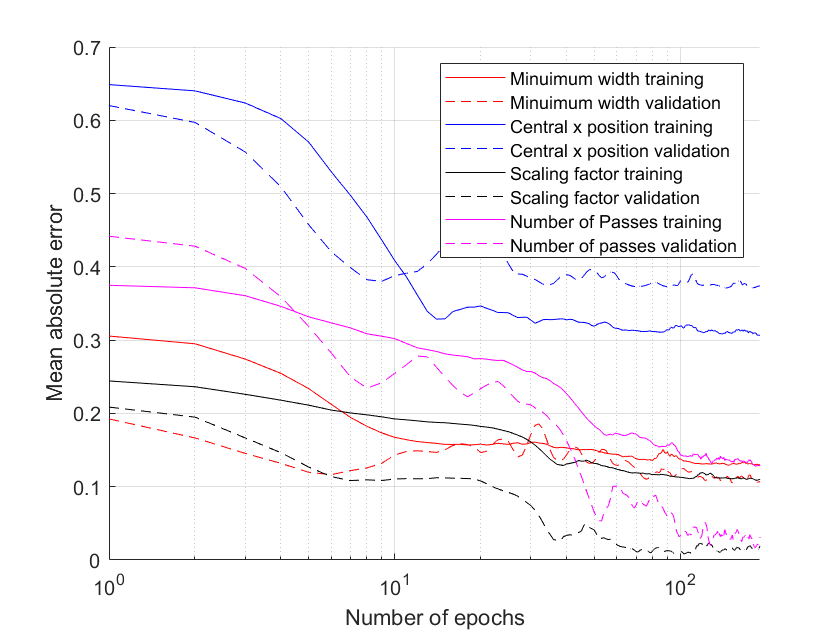

data_train1 = smooth(layer2(:,7));
data_val1 = smooth(layer2(:,16));
data_train2 = smooth(layer2(:,8));
data_val2 = smooth(layer2(:,17));
data_train3 = smooth(layer2(:,9));
data_val3 = smooth(layer2(:,18));
data_train4 = smooth(layer2(:,10));
data_val4 = smooth(layer2(:,19));

figure()
hold on

plot(data_train1,'r-')
plot(data_val1,'r--')
plot(data_train2,'b-')
plot(data_val2,'b--')
plot(data_train3,'k-')
plot(data_val3,'k--')
plot(data_train4,'m-')
plot(data_val4,'m--')
set(gca,'xscale','log')

legend({'Minuimum width training','Minuimum width validation','Central x position training','Central x position validation','Scaling factor training','Scaling factor validation','Number of Passes training','Number of passes validation'})
xlabel('Number of epochs')
ylabel('Mean absolute error')
grid on